## Definición de Problema

clear;
CostFunc = "Dropwave";                                                               % Función de costo a optimizar

PosMax = 10;                                                                            % Límite superior para el valor de las variables desconocidas.
PosMin = -PosMax;                                                                       % Límite inferior para el valor de las variables desconocidas
VarDims = 2;                                                                            % No. Variables desconocidas (Varibles de decisión). Dims de posición de partículas

VelMax = 0.2*(PosMax - PosMin);                                                         % Velocidad máxima es un 20% de la diferencia en posiciones
VelMin = -VelMax;                                                                       % Velocidad mínima es solo el negativo de la máxima

[MeshX, MeshY] = meshgrid(PosMin:0.1:PosMax, PosMin:0.1:PosMax);
Mesh2D = [reshape(MeshX, [], 1) reshape(MeshY, [], 1)];                                 % MeshX y MeshY se convierten en vectores columna y se concatenan
Altura = reshape(CostFunction(Mesh2D,CostFunc), size(MeshX, 1), size(MeshX, 2));        % Evalúa cada fila de Mesh2D en "CostFunction". Luego convierte los resultados en una matriz del tamaño de MeshX
MaxAltura = max(max(Altura));                                                           % Se obtiene dos veces el "max" para sacar el máximo de todas las columnas, luego el de todas las filas.

[MinAltura, IndMinAltura] = min(reshape(Altura,[],1));
Coords_Min = Mesh2D(IndMinAltura,:);

AreaTotal = (PosMax - PosMin)^2;                                                        % Se obtiene el área total donde se podrán mover las partículas
Porcentaje_AreaTotal = 0.1;                                                             % Area de convergencia = Porcentaje del área total
Porcentaje_PartDentroRadio = 0.95;
RadioConvergencia = sqrt((AreaTotal * (Porcentaje_AreaTotal/100)) / pi);                % Radio de convergencia (Suponiendo área circular) = Despejar para el radio de un círculo en la fórmula para el área   

IteracionesMax = 500;                                                                   % Iteraciones máximas para converger
Threshold_PosDiff = 0.001;

## Parámetros PSO

NoParticulas = 50;                              % No. de partículas

% Coeficientes de Constricción
Kappa = 1;
Phi1 = 2.05;
Phi2 = 2.05;

% Variación de los parámetros propuestos en el paper de Clerc y Kennedy
Intervalo = 15;
VecKappa = 0.1 : Kappa*2 / (Intervalo-1)  : Kappa*2 + 0.1;                      % Vector con "Intervalo" valores entre 0 y 2*Kappa 
VecPhi1 = 0.1 : Phi1*2 / (Intervalo-1) : Phi1*2 + 0.1;                          % Vector con "Intervalo" valores entre 0 y 2*Phi1
VecPhi2 = 0.1 : Phi2*2 / (Intervalo-1) : Phi2*2 + 0.1;                          % Vector con "Intervalo" valores entre 0 y 2*Phi2

[MatPhi1, MatPhi2, MatKappa] = meshgrid(VecPhi1, VecPhi2, VecKappa);    % Meshgrid con todos los valores posibles de Phi1, Phi2 y Kappa
MatPhi1 = reshape(MatPhi1,[], 1);                                       % Se convierten todos los "Mesh" en vectores columna
MatPhi2 = reshape(MatPhi2,[], 1);
MatKappa = reshape(MatKappa,[], 1);

Points = size(MatKappa, 1);                                             % Número de filas de Kappa. Esto es igual al número de puntos (Phi1, Phi2, Kappa) a evaluar
NoPruebas = 20;
Pruebas = zeros(Points,NoPruebas);

## Main Loop

Iteraciones_History = zeros(Points,1);                                  % "Iteraciones_History": Iteraciones requeridas para converger en cada variación de parámetros

for k = 1:NoPruebas
    
    for j = 1:Points                                                       
        
        % Variación en los parámetros del algoritmo.
        % Basado en el paper publicado por Clerc y Kennedy (2002)
        
        Phi1 = MatPhi1(j);                                                  % Phi1 = Fila "j" de MatPhi1
        Phi2 = MatPhi2(j);                                                  % Phi2 = Fila "j" de MatPhi2
        Kappa = MatKappa(j);                                                % Kappa = Fila "j" de Kappa
    
        Phi = Phi1 + Phi2;                                                  
        Chi = 2*Kappa / abs(2 - Phi - sqrt(Phi^2 - 4*Phi));
    
        W = Chi;                                                            % Coeficiente de inercia.
        WDamp = 1;                                                          % Coeficiente de amortiguamiento del coeficiente inercial
        C1 = Chi*Phi1;                                                      % Coeficiente de aceleración local (Personal)
        C2 = Chi*Phi2;                                                      % Coeficiente de aceleración global
        
        Iteraciones = 1;
        
        % Inicialización de parámetros para la simulación
        
        Posicion_Actual = unifrnd(PosMin, PosMax, [NoParticulas VarDims]);      % Posición (Random) de todas las partículas. Distribución uniforme.     Dims: NoParticulas X VarDims
        Posicion_Previa = Posicion_Actual;
        Posicion_LocalBest = Posicion_Actual;                                   % Las posiciones que generaron los mejores costos en las partículas     Dims: NoParticulas X VarDims
        Velocidad = zeros([NoParticulas VarDims]);                              % Velocidad de todas las partículas. Inicialmente 0.                    Dims: NoParticulas X VarDims
        Costo_Local = CostFunction(Posicion_Actual, CostFunc);                  % Evaluación del costo en la posición actual de la partícula.           Dims: NoPartículas X 1 (Vector Columna)
        Costo_LocalBest = Costo_Local;
        
        [Costo_GlobalBest, Fila] = min(Costo_LocalBest);                        % "Global best": El costo más pequeño del vector "CostoLocal"           Dims: Escalar
        Posicion_GlobalBest = Posicion_Actual(Fila, :);                         % "Global best": Posición que genera el costo más pequeño               Dims: 1 X VarDims
        
        Costo_History = zeros([IteracionesMax 1]);                              % Historial de todos los "Costo_Global" o global best
        Costo_History(1) = Costo_GlobalBest;                                    % La primera posición del vector es el primer "Global Best"
        
        % Corrida del algoritmo de PSO.
        % Se toma nota del número de iteraciones requeridas.
        for i = 2:IteracionesMax
            
            R1 = rand([NoParticulas VarDims]);                                              % R1 y R2: Valores aleatorios normalmente distribuidos
            R2 = rand([NoParticulas VarDims]);
            Posicion_Previa = Posicion_Actual;
            
            % Actualización de Velocidad
            Velocidad = W * Velocidad ...                                                   % Término inercial
                + C1 * R1 .* (Posicion_LocalBest - Posicion_Actual) ...                     % Componente cognitivo
                + C2 * R2 .* (Posicion_GlobalBest - Posicion_Actual);                       % Componente social
            
            Velocidad = max(Velocidad, VelMin);                                             % Se truncan los valores de velocidad en el valor mínimo y máximo
            Velocidad = min(Velocidad, VelMax);
            
            % Actualización de Posición
            Posicion_Actual = Posicion_Actual + Velocidad;
            Posicion_Actual = max(Posicion_Actual, PosMin);                                 % Se truncan los valores de posición en el valor mínimo y máximo
            Posicion_Actual = min(Posicion_Actual, PosMax);
            
            % Actualización de Local y Global Best
            Costo_Local = CostFunction(Posicion_Actual, CostFunc);                          % Actualización de los valores del costo
            Costo_LocalBest = min(Costo_LocalBest, Costo_Local);                            % Se sustituyen los costos que son menores al "Local Best" previo
            Costo_Change = (Costo_Local < Costo_LocalBest);                                 % Vector binario que indica con un 0 cuales son las filas de "Costo_Local" que son menores que las filas de "Costo_LocalBest"
            Posicion_LocalBest = Posicion_LocalBest .* Costo_Change + Posicion_Actual;      % Se sustituyen las posiciones correspondientes a los costos a cambiar en la linea previa
            
            [Costo_Global, Fila] = min(Costo_LocalBest);                                    % Valor mínimo de entre los valores de "Costo_Local"
            
            if Costo_Global < Costo_GlobalBest                                              % Si el nuevo costo global es menor al "Global Best" entonces
                Costo_GlobalBest = Costo_Global;                                            % Se actualiza el valor del "Global Best"
                Posicion_GlobalBest = Posicion_Actual(Fila, :);                             % Y la posición correspondiente al "Global Best"
            end
            
            % Actualización del historial de "Best Costs"
            Costo_History(i) = Costo_GlobalBest;                                            
            
            % Actualización del coeficiente inercial
            W = W * WDamp;
            
            % Actualizar el número de iteraciones
            Iteraciones = Iteraciones + 1;
            
            Dists_ToMin = sqrt(sum((Posicion_Actual - Coords_Min).^2, 2));                      % Distancias de todas las partículas al mínimo global                       
            Particulas_DentroRadio = sum(Dists_ToMin < RadioConvergencia);                      % Se cuentan todas las partículas cuya distancia al mínimo es menor al radio de convergencia.
            Criterios(1) = Particulas_DentroRadio > Porcentaje_PartDentroRadio*NoParticulas;    % Criterio 1 = Detener si cierto porcentaje de las partículas llega al centro

            Dists_ToPrev = sqrt(sum((Posicion_Actual - Posicion_Previa).^2, 2));                % Distancia de la posición actual de cada partícula a su posición previa
            Particulas_Quietas = sum(Dists_ToPrev < Threshold_PosDiff);                         % Se cuentan todas las partículas que se hayan movido una distancia menor a "Threshold_PosDiff"
            Criterios(2) = Particulas_Quietas == NoParticulas;                                  % Criterio 2 = Detener si el número de partículas "quietas" es menor al total de partículas.
            
            Criterios(3) = i == IteracionesMax;                                                 % Criterio 3 = Detener si se llega al número de iteraciones máximo.
            
            if (Criterios(1) && Criterios(2)) || Criterios(3)
                break
%                 Criterios_Activados = find(Criterios(2:end) > 0);
%                 if any(Criterios_Activados > 0)
%                     break
%                 end
                
            end
            
        end
        
        Iteraciones_History(j) = Iteraciones;
        
    end
    
    Pruebas(:,k) = Iteraciones_History;
    disp("Prueba " + num2str(k) + " terminada");

end

Prueba 1 terminada
Prueba 2 terminada
Prueba 3 terminada
Prueba 4 terminada
Prueba 5 terminada
Prueba 6 terminada
Prueba 7 terminada
Prueba 8 terminada
Prueba 9 terminada
Prueba 10 terminada
Prueba 11 terminada
Prueba 12 terminada
Prueba 13 terminada
Prueba 14 terminada
Prueba 15 terminada
Prueba 16 terminada
Prueba 17 terminada
Prueba 18 terminada
Prueba 19 terminada
Prueba 20 terminada


NombreMat = "Pruebas_" + CostFunc + ".mat";
save(NombreMat, 'Pruebas');
disp("Proceso Finalizado");

Proceso Finalizado


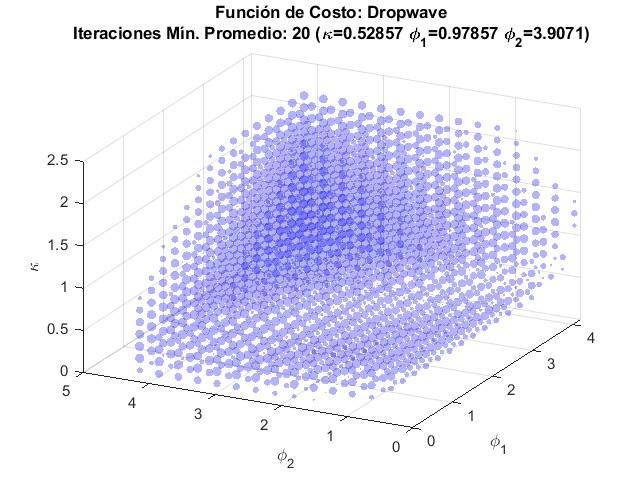

%load(NombreMat);

Iteraciones = median(Pruebas,2);
Iteraciones_HistoryNorm = 1 - (Iteraciones/IteracionesMax);

IterMax = max(nonzeros(Iteraciones_HistoryNorm));
IterMin = min(nonzeros(Iteraciones_HistoryNorm));
Threshold = 0.85 * (IterMax - IterMin) + IterMin;

FilteredMin = min(Iteraciones_HistoryNorm(Iteraciones_HistoryNorm > Threshold));
FilteredMax = max(Iteraciones_HistoryNorm(Iteraciones_HistoryNorm > Threshold) - FilteredMin);

FilteredIter = (Iteraciones_HistoryNorm(Iteraciones_HistoryNorm > Threshold) - FilteredMin) / FilteredMax;
FilteredPhi1 = MatPhi1(Iteraciones_HistoryNorm > Threshold);
FilteredPhi2 = MatPhi2(Iteraciones_HistoryNorm > Threshold);
FilteredKappa = MatKappa(Iteraciones_HistoryNorm > Threshold);

BaseInterval = [0 1];
NewInterval = [1 40];

Remap = @(X, XBase, XNew) floor(XNew(1) + (X - XBase(1)) * (XNew(2) - XNew(1)) / (XBase(2) - XBase(1)));

FilteredIter = Remap(FilteredIter, BaseInterval, NewInterval);

figure(1); clf;
%figure('visible','on');
axis equal; grid on;
axis([min(MatPhi1) max(MatPhi1) min(MatPhi2) max(MatPhi2) min(MatKappa) max(MatKappa)])

scatter3(FilteredPhi1, FilteredPhi2, FilteredKappa, FilteredIter,'blue','filled');
alpha 0.3;

[ItMin, ItMinIndex] = min(Iteraciones);

xlabel("\phi_1");
ylabel("\phi_2");
zlabel("\kappa");
title({"Función de Costo: " + CostFunc; "Iteraciones Mín. Promedio: " + ItMin ...
                                        + " (\kappa=" + num2str(MatKappa(ItMinIndex)) ...
                                        + " \phi_1=" + num2str(MatPhi1(ItMinIndex)) ...
                                        + " \phi_2=" + num2str(MatPhi2(ItMinIndex)) + ")"});